# Graficación de cruces por cero y energía de corta duración

Se grafica la señal de audio con respecto al tiempo y se grafican las dos variables.

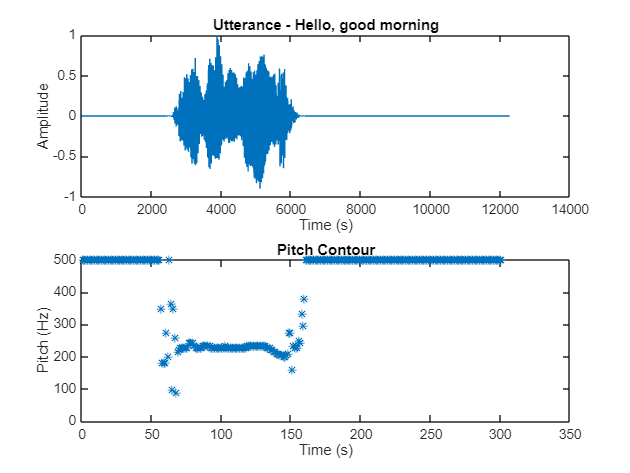

[audioIn,fs] = audioread("C:\Users\alfre\Music\Audios_Reto2\Mariam\Mariam4_aug1.wav");
windowLength = round(0.03*fs);
overlapLength = round(0.025*fs);

f0 = pitch(audioIn,fs,WindowLength=windowLength,OverlapLength=overlapLength,Range=[50,500]);

%figure
%tiledlayout(2,1)

%nexttile()
subplot(2,1,1), plot(audioIn)
ylabel("Amplitude")
xlabel("Time (s)")
title("Utterance - Hello, good morning")

%nexttile()
subplot(2,1,2), plot(f0,"*");
ylabel("Pitch (Hz)")
xlabel("Time (s)")
title("Pitch Contour")

Energía de corta duración

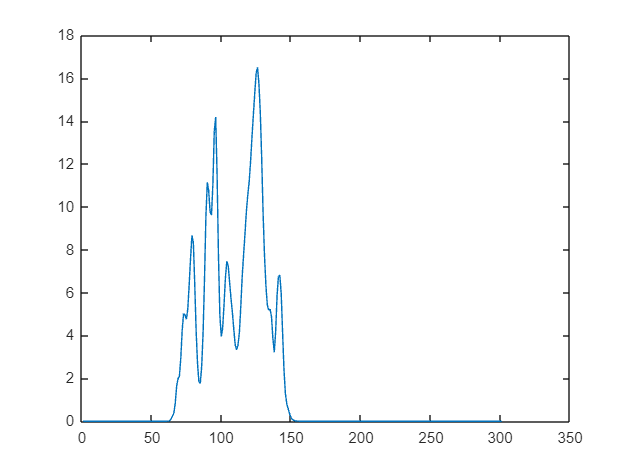

[segments,~] = buffer(audioIn,windowLength,overlapLength,"nodelay");
ste = sum((segments.*hamming(windowLength,"periodic")).^2,1);
figure
plot(ste)

Tasa de cruces por cero

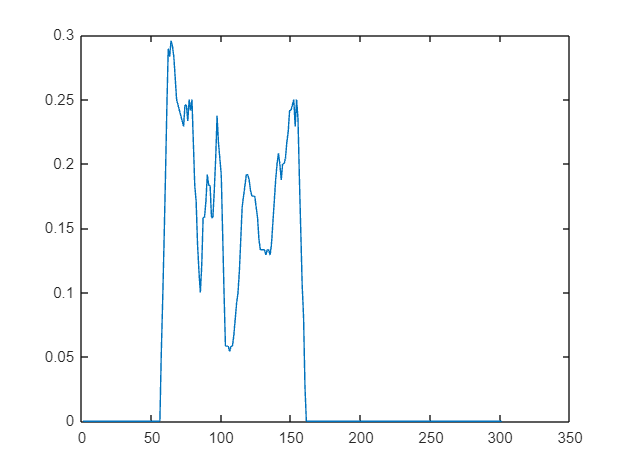

zcr = zerocrossrate(audioIn,WindowLength=windowLength,OverlapLength=overlapLength);
figure
plot(zcr)

Se combinan ambas variables.

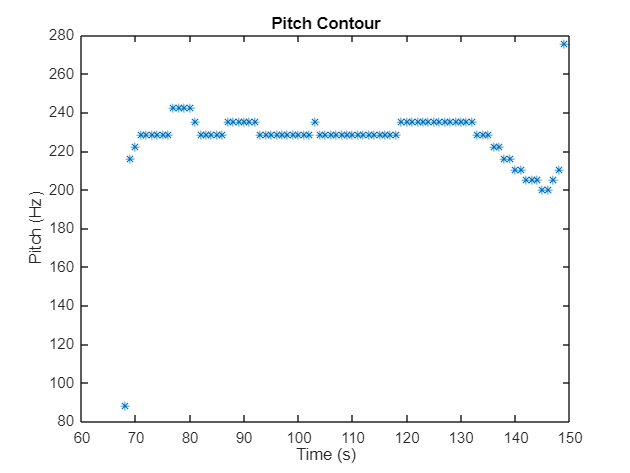

energyThreshold = 0.22;
zcrThreshold = 0.26;
isSpeech = ste(:) > energyThreshold;
isVoiced = zcr < zcrThreshold;
voicedSpeech = isSpeech & isVoiced;
f01 = pitch(audioIn,fs,WindowLength=windowLength,OverlapLength=overlapLength,Range=[50,500]);
f01(~voicedSpeech) = NaN;
figure
plot(f01,"*");
ylabel("Pitch (Hz)")
xlabel("Time (s)")
title("Pitch Contour")